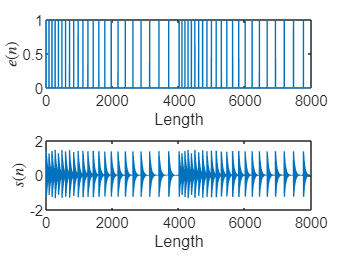

% 1.2.1(1)
z = 1;
p = [1, -1.3798, 0.9506];
roots(p);
zplane(z, p)
freqz(z, p)
impz(z, p)
stem(filter(z, p, [1, zeros(1, 300)]))
title("单位样值响应");
xlabel("n");
ylabel("振幅")

% 1.2.2(7)
sound(unitSampleSignal(8000, 200, 1));
sound(unitSampleSignal(8000, 300, 1));

% 1.2.2(8)
e = pitchGenerating(8000, 1);
L = length(e);
sound(e);

% 1.2.2(9)
s = filter(z, p, e);
sound(s);
Fs = 8000;

figure;
subplot(2, 1, 1);
plot(e);
xlabel("Length");
ylabel("$e(n)$", Interpreter="latex");
subplot(2, 1, 2);
plot(s);
xlabel("Length");
ylabel("$s(n)$", Interpreter="latex");

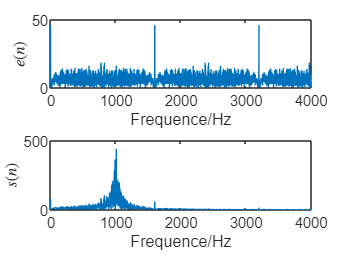


% 画出 e(n), s(n) 频谱
e_fft = fft(e);
s_fft = fft(s);
freq = Fs * (0: (L / 2)) / L;

figure;
subplot(2, 1, 1);
plot(freq, abs(e_fft(1: L / 2 + 1)));
xlabel("Frequence/Hz");
ylabel("$e(n)$", Interpreter="latex");

subplot(2, 1, 2);
plot(freq, abs(s_fft(1: L / 2 + 1)));
xlabel("Frequence/Hz");
ylabel("$s(n)$", Interpreter="latex");


% 1.2.4(12)
newP = rotAngle(p, 0.0375 * pi)

newP =     1.0000   -1.2083    0.9506


newPL1 = rotAngle(1.1 * p, 0.0375 * pi)

newPL1 =     1.1000   -1.3291    1.0457


newPL2 = rotAngle(1.2 * p, 0.0375 * pi)

newPL2 =     1.2000   -1.4499    1.1407


newPS1 = rotAngle(0.9 * p, 0.0375 * pi)

newPS1 =     0.9000   -1.0875    0.8555


newPS2 = rotAngle(0.8 * p, 0.0375 * pi)

newPS2 =     0.8000   -0.9666    0.7605


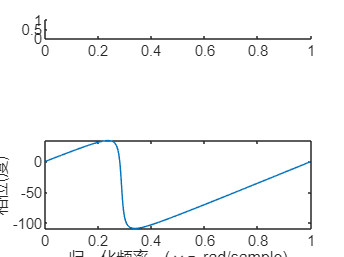

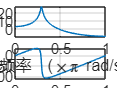

figure
subplot(5, 1, 1)
freqz(z, newP)

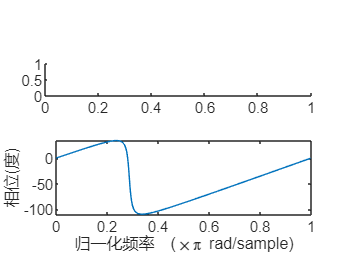

subplot(5, 1, 2)
freqz(z, newPL1)

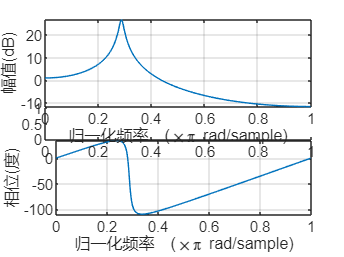

subplot(5, 1, 3)
freqz(z, newPL2)

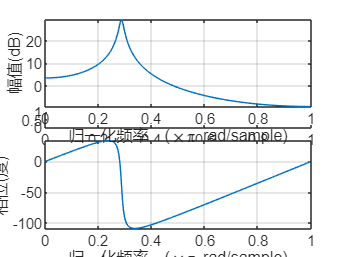

subplot(5, 1, 4)
freqz(z, newPS1)

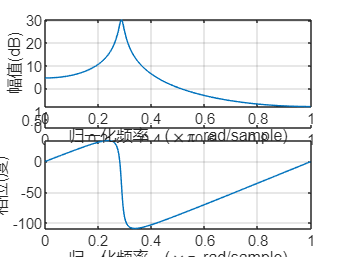

subplot(5, 1, 5)
freqz(z, newPS2)

function s = unitSampleSignal(Fs, freq, duration)
    N = round(Fs / freq);
    NS = round(freq * duration);
    s = zeros(1, round(Fs * duration));
    for k = 0: NS - 1
        s(k * N + 1) = 1;
    end
end

function s = pitchGenerating(Fs, duration)
    len = round(Fs * duration);
    s = zeros(1, len);
    k = 1;
    while k <= len
        s(k) = 1;
        % 直接定位到有脉冲的段序号
        m = ceil(k / Fs / 0.01);
        k = k + 80 + 5 * mod(m, 50);
    end
end

function newP = rotAngle(v, deltaAngle)
    p = roots(v);
    newP = poly(p .* exp(deltaAngle * sign(imag(p)) * 1i)) * v(1);
end